loadspice("miniproject1_hysteretic_oscillator.txt"); 

%loadspice("miniproject1_hysteretic_oscillator_2.txt");  

%loadspice("miniproject1_hysteretic_oscillator_3.txt");  

t = time; 
v = n007; %n006; %n005 %n004
save data.mat t v;

%Test Code for 1 Simulation
trial1 = v{1};

trial1 =          0    0.2158    0.2161    0.2160    0.2168    0.2194    0.2224    0.2278    0.2382    0.2506    0.2686    0.2901    0.3195    0.3527    0.4022    0.4438    0.4814    0.5120    0.5444    0.5775    0.6202    0.6751    0.7626    0.9081    1.1989    1.4767    1.7272    2.0209    2.2364    2.5211    2.8150    2.9465    3.0141    3.0686    3.0822    3.0909    3.0975    3.1035    3.1069    3.1102    3.1125    3.1146    3.1161    3.1174    3.1183    3.1191    3.1201    3.1205    3.1207    3.1208


time1 = t{1};

time1 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


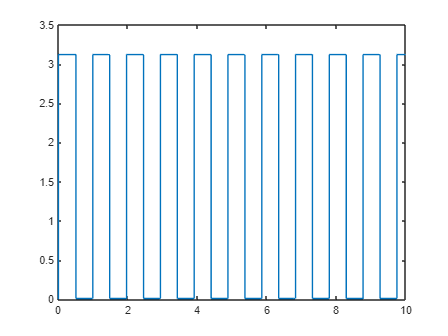

plot(time1,trial1);

[pks,locs] = findpeaks(trial1, 'MinPeakDistance',90);

pks =     3.1209    3.1209    3.1209    3.1209    3.1209    3.1209    3.1209    3.1209    3.1209    3.1209    3.1209


locs =           51         213         367         526         683         842         998        1147        1320        1462        1618


time1(locs);

ans =     0.0000    0.9910    1.9643    2.9376    3.9109    4.8841    5.8574    6.8299    8.0458    8.7763    9.7497


period = mean(diff(time1(locs)));

period = 0.9750

save period.mat period

%Find the period of each simulation:
periods = []


periods =

     []



for i=1:1025
    trial = v{i};
    time = t{i};
    [pks, locs]= findpeaks(trial, 'MinPeakDistance',90);
    period = mean(diff(time(locs)));
    periods(i) = period;
end
save period.mat periods

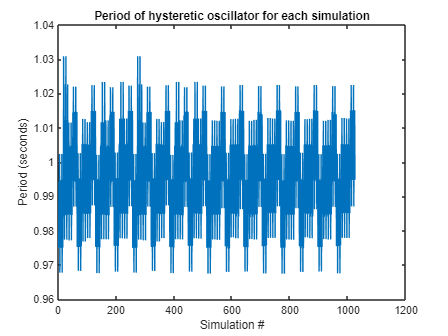

plot(periods)
xlabel('Simulation #'); 
ylabel('Period (seconds)'); 
title('Period of hysteretic oscillator for each simulation')

%need to be within +-10% of 1s (1s +- .1s)
error = [];
number_of_errors = 0; 
for period = 1:1025
    error(period) = (periods(period) - 1)*100;
end

for k = 1:1025
    if error(k) > 10 | error(k) < -10
        number_of_errors = number_of_errors +1;
    end
end
disp(number_of_errors)

     0



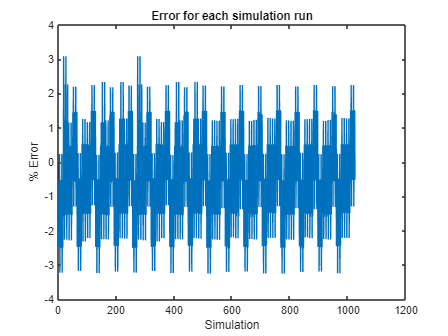

plot(error)
xlabel('Simulation')
ylabel('% Error')
title('Error for each simulation run')